# **Actividad 1. Mapeo de coordenadas**

## **Objetivo:**

Implementar el código requerido para generar un **mapeo** del siguiente sistema global al sistema local de referencia del robot móvil y           viceversa.

## 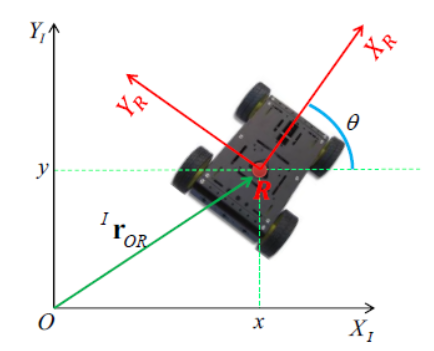

**y Obtener** el mapeo de las siguientes coordenadas inerciales, hacia un marco de referencia local y comprobar si se obtienen las coordenadas iniciales con el mapeo inverso

a) **(-5, 9, -2°)**

b) **(-3, 8, 63°)**

c) **(5, -2, 90°)**

d) **(0, 0, 180°)**

e) **(-6, 3, -55°)**

## **Procedimiento:**

Limpieza de pantalla

clear all
close all
clc

tic

Se declaran todas las cordenadas iniciales, para cada uno de los tiempos, en un vector de 

%Defino coordenadas inerciales para un tiempo 
x = [-5 -3  5   0 -6]; %Posiciones en el eje x
y = [ 9  8 -2   0  3]; %Posiciones en el eje y
th =[-2 63 90 180 -55]; %Orientaciones del robot


Se llama a la funcion funcion mapeo, pasandole como argumento la posicion en x, posicion en y y el angulo de la primera cordenada inercial, que se encuntran en los vectores definidos previamente.

Este proceso se repite para cada una de las coordenadas, por lo cual solo se va cambiando el indice de los vectores. 

mapeo(x(1),y(1),th(1))

xi_local_1 =    10.2644
    0.8012
   -2.0000


magnitud = 10.2956

xi_inercial_1 =    -5.0000
    9.0000
   -2.0000


mapeo(x(2),y(2),th(2))

xi_local_1 =    -4.2965
    7.3851
   63.0000


magnitud = 8.5440

xi_inercial_1 =     -3
     8
    63


mapeo(x(3),y(3),th(3))

xi_local_1 =    -0.4524
    5.3661
   90.0000


magnitud = 5.3852

xi_inercial_1 =     5.0000
   -2.0000
   90.0000


mapeo(x(4),y(4),th(4))

xi_local_1 =      0
     0
   180


magnitud = 0

xi_inercial_1 =      0
     0
   180


mapeo(x(5),y(5),th(5))

xi_local_1 =    -3.1320
   -5.9322
  -55.0000


magnitud = 6.7082

xi_inercial_1 =    -6.0000
    3.0000
  -55.0000



 toc

Elapsed time is 0.684761 seconds.


Se declara la funcion mapeo, que como su nombre nos indica, nos va a mapear las coordenadas inerciales a coordenadas locales, y viceversa, ademas de que tambien nos imprime la magnitud del vector resultante. 

Para llevar a cabo esto se siguen los siguientes pasos. 

- Se declara el vector de posicion, que contiene la posicione x, y, y la orientacion. 

- Se declara la matriz de rotacion en z, ya que es el eje a traves del cual rota nuestro robot.

- Se obtienen las cordenadas locales mediante la multiplicaion del vector de posicion por la matriz de rotacion.

                                             

- Usando pitagoras se obtiene la magnitud del vector resultante

- Se realiza la transformacion del marco de referencia local al inercial, lo cual da como resultado las posiciones x, y y la orientacion que le pasamos en un principio a la funcion. Para esto, primero se obtiene la matriz inversa de la matriz de rotacion en z, la cual es multiplicada por el vector de posicion local y de esta forma obtenemos el vector de posicion inercial. 

function mapeo(x1, y1,th1)
    %Vector de posición y matriz de rotación para el eje z
    Pos_1=[x1; y1; th1];
    Rot_1= [cos(th1) -sin(th1) 0;
            sin(th1)  cos(th1) 0;
            0         0      1];
     
    %Realizo mi transformación del marco de referencia inercial al local.... 
    xi_local_1=Rot_1*Pos_1

    %Obtengo la magnitud del vector resultante 
    magnitud = sqrt(xi_local_1(1)^2 + xi_local_1(2)^2)
    
    %Realizo la transformacion del marco de referencia local al inercial
    %para comprobar

    inv_Rot_1 = inv(Rot_1);
    xi_inercial_1 = inv_Rot_1*xi_local_1

end